## Part a)

ra = 40000; % km 
rp = 7000; % km
mu = 398600.4415; % km^3/s^2

a = (ra + rp) / 2; % km
e = ra / a - 1;
p = a*(1-e^2);
b = a*sqrt(1-e^2);
h = sqrt(mu*p);
energy = -mu/(2*a);
period = 2*pi*sqrt(a^3/mu);
period_days = period/60/60/24;
rb = sqrt(b^2 + (a*e)^2)

rb = 2.3500e+04

## Part b)

th0_deg = 90;
th0 = deg2rad(th0_deg);
[r0, v0, E0, E0_deg, gamma0, gamma0_deg, r0_rth, r0_ep, v0_rth, v0_ep, Cep_rth_0, Crth_ep_0]...
    = states(mu, th0_deg, a, e, h, p)

r0 = 1.1915e+04

v0 = 7.0673

E0 = 0.7924

E0_deg = 45.4020

gamma0 = 0.6122

gamma0_deg = 35.0738

r0_rth = 	1.0e+04 *

    1.1915         0


r0_ep = 	1.0e+04 *

    0.0000    1.1915


v0_rth =     4.0611    5.7839


v0_ep =    -5.7839    4.0611


Cep_rth_0 =     0.0000    1.0000
   -1.0000    0.0000


Crth_ep_0 =     0.0000   -1.0000
    1.0000    0.0000


## Part c)

thf_deg = 225;
thf = deg2rad(thf_deg);
[rf, vf, Ef, Ef_deg, gammaf, gammaf_deg, rf_rth, rf_ep, vf_rth, vf_ep, Cep_rth_f, Crth_ep_f]...
    = states(mu, thf_deg, a, e, h, p)

rf = 2.3663e+04

vf = 4.0900

Ef = -1.5807

Ef_deg = -90.5666

gammaf = -0.7784

gammaf_deg = -44.5966

rf_rth = 	1.0e+04 *

    2.3663   -0.0000


rf_ep = 	1.0e+04 *

   -1.6732   -1.6732


vf_rth =    -2.8716    2.9123


vf_ep =     4.0899   -0.0288


Cep_rth_f =    -0.7071   -0.7071
    0.7071   -0.7071


Crth_ep_f =    -0.7071    0.7071
   -0.7071   -0.7071


## Part d)

dt0 = sqrt(a^3/mu)*(E0-sin(E0));
dtf = sqrt(a^3/mu)*(3*pi/2-sin(3*pi/2));
dt = dtf-dt0

dt = 3.2136e+04

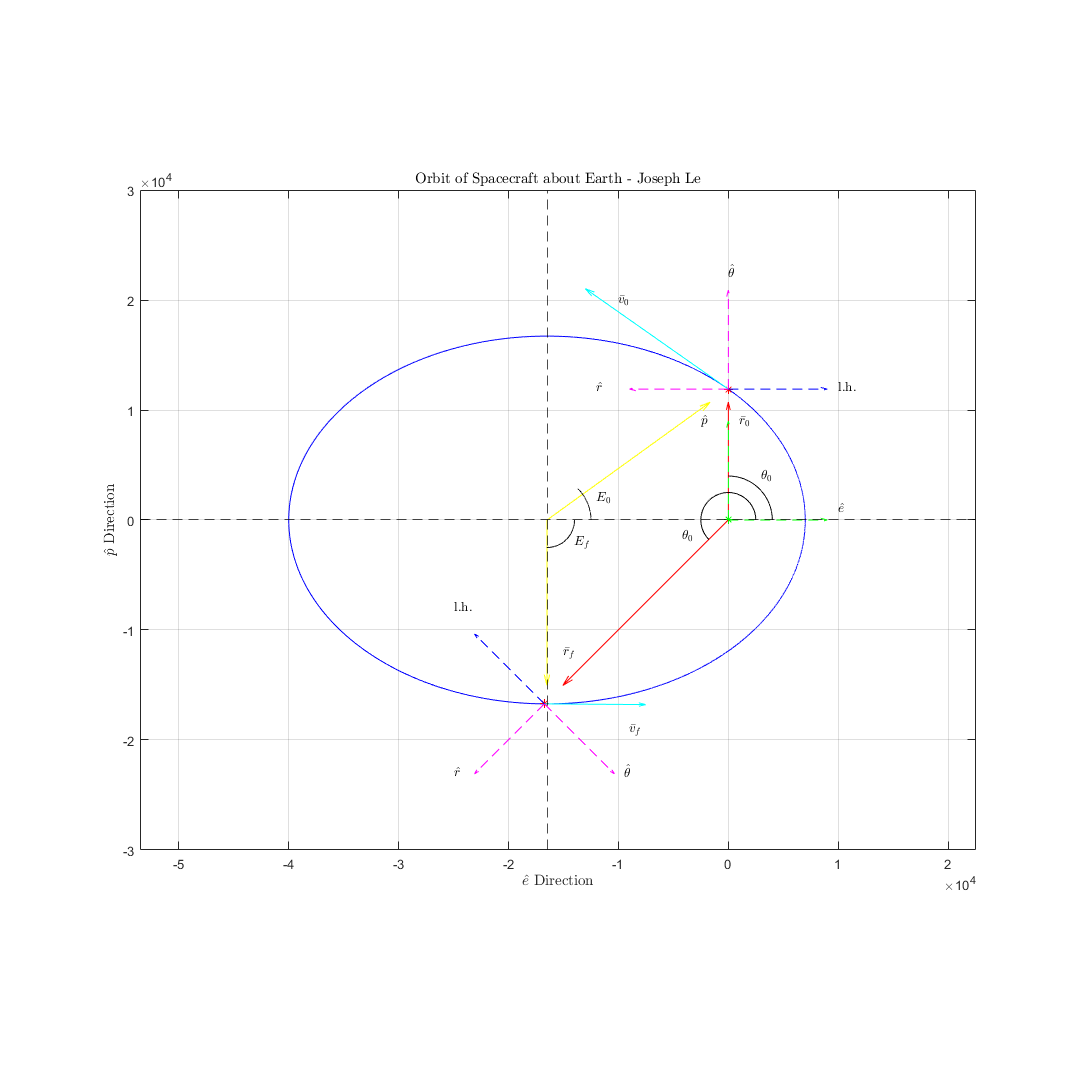

% plot ellipse
th = linspace(0,2*pi,2^14);
r = p./(1+e*cos(th));
rx = r.*cos(th);
ry = r.*sin(th);

% plot aux circle
% E = th;
% rc = a;
% xc = rc*cos(th)-a*e;
% yc = rc*sin(th);

plot(rx,ry,'b')

ylim([-3,3]*10^4)
xlim([-5,2]*10^4)
axis equal
grid on
hold on 
xline(-a*e,'k--')
yline(0,'k--')
% Earth
plot(0,0,'g*')

% Initial
plot(r0_ep(1),r0_ep(2),'r*')
quiver(r0_ep(1),r0_ep(2),'r')
plotcircle(0,0,0,th0,.4e4)
quiver(-a*e,0,(a*e)-cos(pi-th0),r0_ep(2),'y')
plotcircle(-a*e,0,0,E0,.4e4)
quiver(r0_ep(1),r0_ep(2),.25e4*v0_ep(1),.25e4*v0_ep(2),'c')


% Final
plot(rf_ep(1),rf_ep(2),'r*')
quiver(rf_ep(1),rf_ep(2),'r')
plotcircle(0,0,0,thf,.25e4)
quiver(-a*e,0,0,rf_ep(2),'y')
plotcircle(-a*e,0,0,Ef,.25e4)
quiver(rf_ep(1),rf_ep(2),.25e4*vf_ep(1),.25e4*vf_ep(2),'c')



% plot unit vectors
quiver(0,1e4,'g--'), quiver(1e4,0,'g--')
% at initial point
quiver(r0_ep(1),r0_ep(2),-1e4,0,'m--')
quiver(r0_ep(1),r0_ep(2),0,1e4,'m--')
% l.h.0
quiver(r0_ep(1),r0_ep(2),1e4,0,'b--')


% at final point
quiver(rf_ep(1),rf_ep(2),cos(thf)*1e4,sin(thf)*1e4,'m--')
quiver(rf_ep(1),rf_ep(2),-sin(thf)*1e4,cos(thf)*1e4,'m--')
% l.h.0
quiver(rf_ep(1),rf_ep(2),sin(thf)*1e4,-cos(thf)*1e4,'b--')
% Labels
text(-1.2e4,1.2e4,'$$\hat{r}$$','Interpreter','Latex')
text(0,2.25e4,'$$\hat{\theta}$$','Interpreter','Latex')
text(1.e4,1.2e4,'l.h.','Interpreter','Latex')
text(-2.5e4,-2.3e4,'$$\hat{r}$$','Interpreter','Latex')
text(-.95e4,-2.3e4,'$$\hat{\theta}$$','Interpreter','Latex')
text(-2.5e4,-.8e4,'l.h.','Interpreter','Latex')
text(-.25e4,.9e4,'$$\hat{p}$$','Interpreter','Latex')
text(1e4,.1e4,'$$\hat{e}$$','Interpreter','Latex')
text(.3e4,.4e4,'$$\theta_{0}$$','Interpreter','Latex')
text(-.42e4,-.15e4,'$$\theta_{0}$$','Interpreter','Latex')
text(.1e4,.9e4,'$$\bar{r}_{0}$$','Interpreter','Latex')
text(-1.5e4,-1.2e4,'$$\bar{r}_{f}$$','Interpreter','Latex')
text(-1e4,2e4,'$$\bar{v}_{0}$$','Interpreter','Latex')
text(-.9e4,-1.9e4,'$$\bar{v}_{f}$$','Interpreter','Latex')
text(-1.2e4,.2e4,'$$E_{0}$$','Interpreter','Latex')
text(-1.4e4,-.2e4,'$$E_{f}$$','Interpreter','Latex')
xlabel('$$\hat{e}$$ Direction','Interpreter','Latex'),ylabel('$$\hat{p}$$ Direction','Interpreter','Latex')
title('Orbit of Spacecraft about Earth - Joseph Le','Interpreter','Latex')
set(gcf,'position',[0,0,1080,1080])

% legend('Orbital Path','Auxiliary Circle','Spacecraft at Initial Position','Earth',...
%     'Spacecraft at Final Position','Initial Position Vector', 'Final Position Vector')

Function 1: Find States

function [r, v, E, E_deg, gamma, gamma_deg, r_rth, r_ep, v_rth, v_ep, Cep_rth, Crth_ep] = states(mu, th_deg, a, e, h, p)
th = deg2rad(th_deg); % degrees
r = p/(1+e*cos(th)); % km
v = sqrt(mu*(2/r-1/a)); % km/s
% xi = sqrt((1+e)/(1-e));
E = 2*atan(sqrt((1-e)/(1+e)) * tan(th/2)); % radians
E_deg = rad2deg(E); % degrees
gamma = acos(h/(v*r)); % radians
if th_deg > 180
    gamma = - gamma;
end
gamma_deg = rad2deg(gamma); % degrees

Cep_rth = [cos(th), sin(th); -sin(th), cos(th)];
Crth_ep = [cos(th), -sin(th); sin(th), cos(th)];

r_ep = r*[cos(th), sin(th)]; % km
v_rth = v*[sin(gamma), cos(gamma)]; % km/s

r_rth = (Cep_rth*r_ep')'; % km
v_ep = (Crth_ep*v_rth')'; % km/s
end

Function 2: Plot Circle

function plotcircle(x0,y0,theta0,thetaf,r)
th = linspace(theta0,thetaf,2^10);
x = r*cos(th)+x0;
y = r*sin(th)+y0;
plot(x,y,'k')
end